# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_6_Data_Analysys

## **Smoothing Data with a Moving Window**

Time series data often contain **noise** or **seasonal fluctuations** that can obscure the underlying pattern or long-term trend.

A common way to make these structures clearer is by applying a **moving-window smoothing technique**.

This method computes a statistic—typically the mean—over a fixed-length window of consecutive observations, then slides the window across the series to create a smoother version of the original data.

The larger the window, the more the short-term noise is reduced, although some of the true signal may also be smoothed away.

In this activity, you will learn how to perform smoothing interactively using the **Smooth Data** Live Editor Task.

You will create a smoothed series from the input data `y` by computing the **centered 3-point moving average**, visualize the results, and compare the original and smoothed curves to observe the effect of different window sizes.

Consider data affected by sesonality. Take a window.

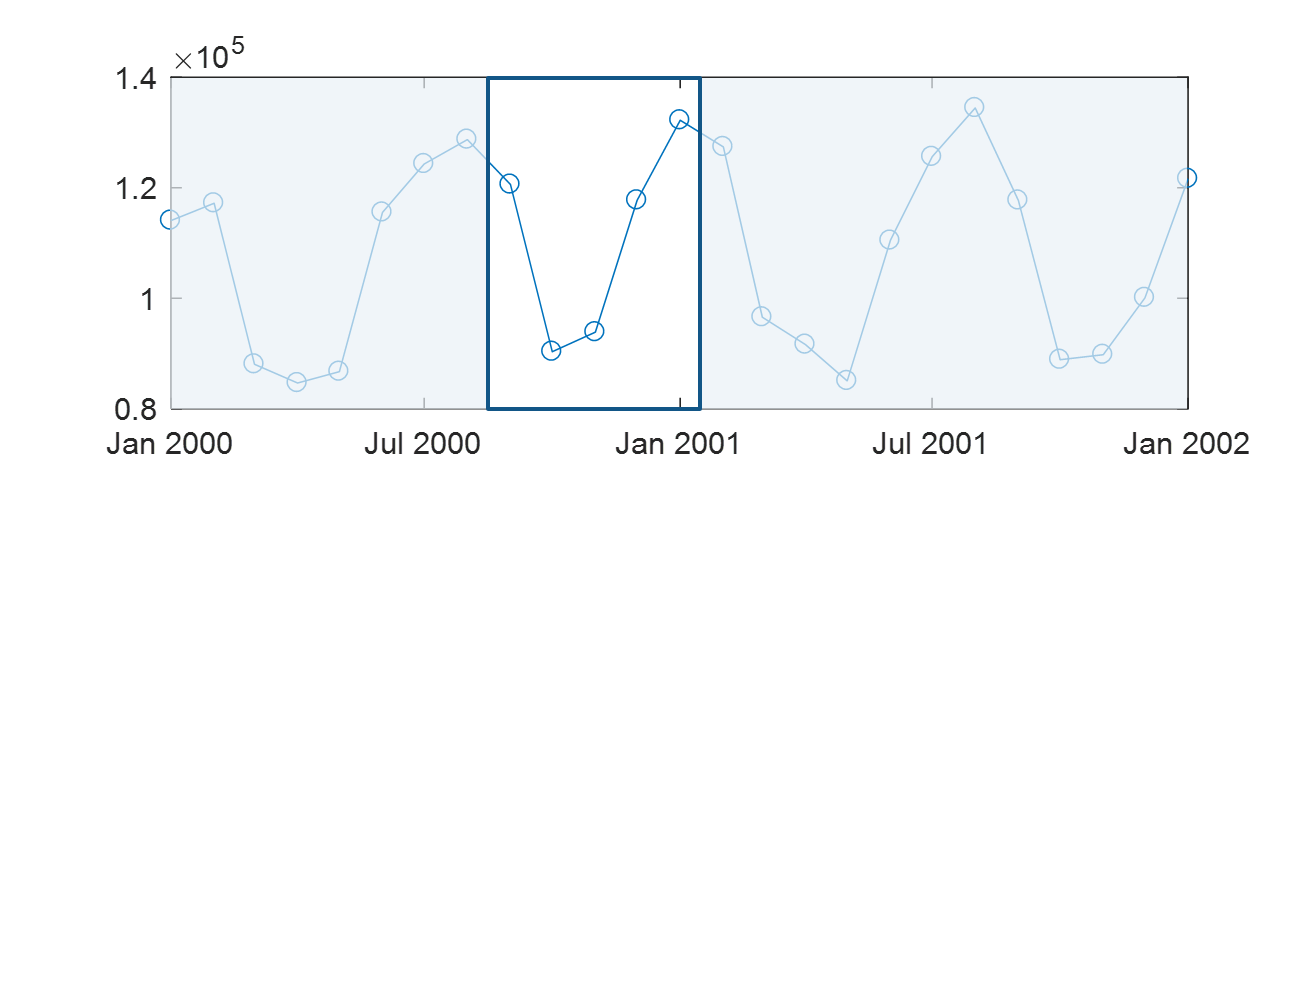

compute the mean or another statistic.

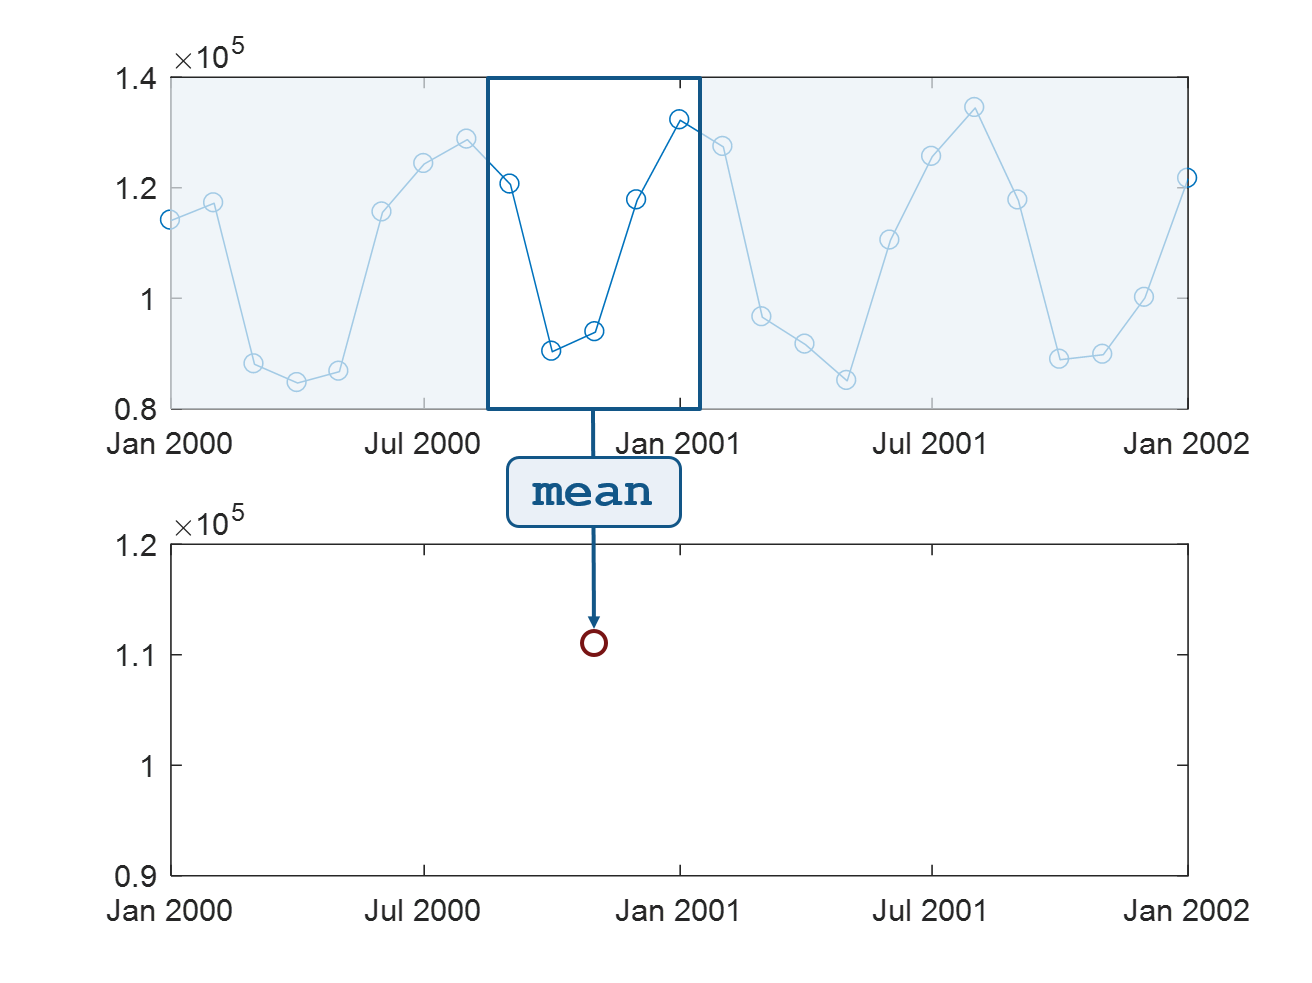

Slide the window across one data point and repeat the calculation for the new subset.

Keep sliding the window across the data.

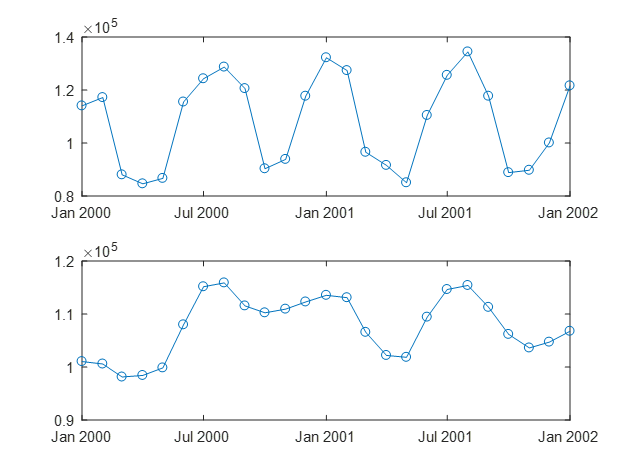

The given statistic is computed for each window. The line plot created from the moving window statistic shows how the original data is smoothed.

You can interactively program how to smooth data with the **Smooth Data** Live Editor task.

Create a vector named `ySm` that contains the centered 3-point moving average of `y`. To do this,

- Set **Input data** to `y`.

- Set **X-axis** to `x`.

- Set **Smoothing method** to `Moving` `mean` with a `Moving` `window` that is `Centered` and `3` elements long.

Display the results by keeping both `Input` `data` and `Smoothed` `Data` selected.

% Smooth input data
[ySm,winSize] = smoothdata(y,"movmean",3,SamplePoints=x);

% Display results
figure
plot(x,y,SeriesIndex=6,DisplayName="Input data")
hold on
plot(x,ySm,SeriesIndex=1,LineWidth=1.5,DisplayName="Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
xlabel("x")
clear winSize


The bigger the window, the more you smooth out the noise, but also the signal. 